clear, clc, clf
format short

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 4);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["alt", "tempR", "presureLb_ft_2", "densitySlug_ft_3"];
opts.VariableTypes = ["double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
altTable = readtable("C:\Users\nicho\OneDrive\Documents\MATLAB\princ areo and astro\/Alt_Table - Sheet1.csv", opts);

% Convert to output type
altTable = table2array(altTable);

% Clear temporary variables
clear opts

% Display results
altTable

altTable = 1.0e+04 *

    0.0001    0.0519    0.2116    0.0000
    0.0002    0.0519    0.2116    0.0000
    0.0003    0.0519    0.2116    0.0000
    0.0004    0.0519    0.2116    0.0000
    0.0005    0.0519    0.2116    0.0000
    0.0006    0.0519    0.2116    0.0000
    0.0007    0.0519    0.2116    0.0000
    0.0008    0.0519    0.2116    0.0000
    0.0009    0.0519    0.2116    0.0000
    0.0010    0.0519    0.2115    0.0000



% specify constants
TaSSl = 30000;
AR = 9.19; % aspect ratio
angle = 30; %degrees
wingArea = 1200; % ft^2
engineWeight = 3135; % lb
engineQuantity = 2; % #
cd0 = 0.01;
fuelWeight = 10000; %lb
TSFC = 0.86;
distanceTraveled = 22233000; %ft
ct = TSFC/3600;
emptyWeight = 3800+950+20000+(wingArea*12)+(engineQuantity*engineWeight);
maxFuelLoad = 38500;
weight = emptyWeight+maxFuelLoad

weight = 83920


e = 4.61*(1-0.045*AR^0.68)*((cos(deg2rad(angle))).^0.15)-3.1;  

densitySSL = altTable(1,4); % density at specifyed altitude
temperatureSSL = altTable(1,2); % temperature at specified altitude
pressureSSL = altTable(1,3); % pressure at specefied altitude



% end constants



% airfoil
%NACA 4412 ✡
alpha0 = -4;
a0 = 0.1056;
a = 0.0741;
alpha = 1.377;
cL = 0.65;
cd = 0.0061;
CD = 0.02673;
cLmax_flaps = 2.7;
alphamax_flaps = 8.7;
alpha0_flaps = -15.2;
a0_flaps = 0.113;
a_flaps = 0.07771;
CLmax_flaps = 1.857;

% end airfoil

% Takeoff 

takeoffDistanceLondon = 1.44*weight^2/(32.2*altTable(82,4)*wingArea*0.4017*TaSSl*(altTable(82,4)/densitySSL))

takeoffDistanceLondon = 9.2065e+03

takeoffDistanceAtlanta = 1.44*weight^2/(32.2*altTable(1026,4)*wingArea*0.4017*TaSSl*(altTable(1026,4)/densitySSL))

takeoffDistanceAtlanta = 9.7318e+03

vpa(takeoffDistanceLondon)

$$ans = 9206.5201477400023577501997351646$$

vpa(takeoffDistanceAtlanta)

$$ans = 9731.815058095358835998922586441$$

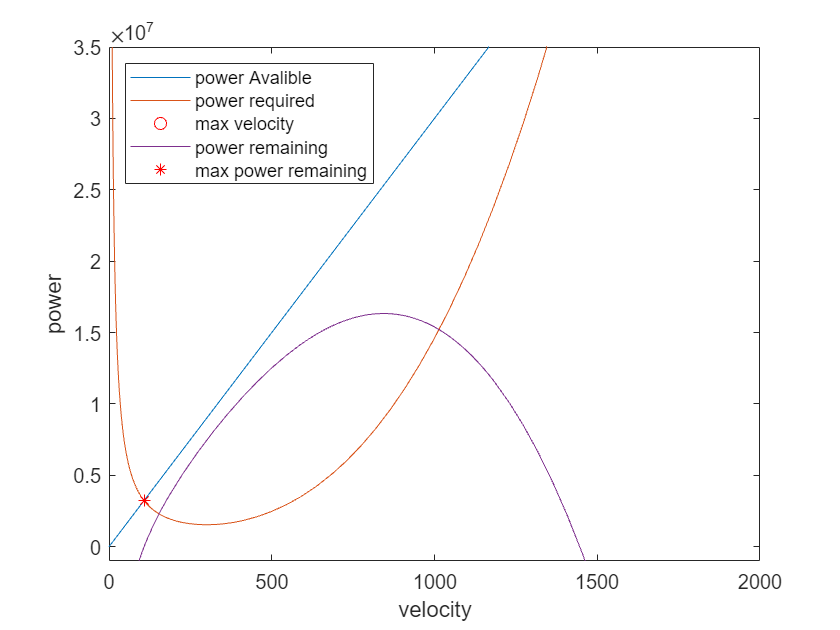


% end takoff


% alt = ssl
altitude = 1; % altitude in feet
density = altTable(altitude,4); % density at specified altitude
temperature = altTable(altitude,2); % temperature at specified altitude
pressure = altTable(altitude,3); % pressure at specefied altitude

speedOfSound = sqrt(1.4*1716*temperature);

Cl = @(velocity) weight*2/(wingArea*density*(velocity.^2));
Cd = @(velocity) cd0 + (weight*2/(wingArea*density*(velocity.^2)))^2/(pi*e*AR);

thrustRequired = @(velocity) weight/((weight*2/(wingArea*density*(velocity.^2)))/(cd0 + (weight*2/(wingArea*density*(velocity.^2)))^2/(pi*e*AR)));

thrustAvalible = TaSSl*(density/densitySSL);

powerRequired = @(velocity) (weight./((weight.*2./(wingArea.*density.*(velocity.^2)))./(cd0 + (weight.*2./(wingArea.*density.*(velocity.^2))).^2./(pi*e*AR)))).*velocity;
powerAvalible = @(velocity) TaSSl*(density/densitySSL).*velocity;

powerRemaining = @(velocity) -(-powerAvalible(velocity)+powerRequired(velocity));



fplot(powerAvalible, [0 2000])
hold on;
fplot(powerRequired,[0 2000])
plot(fzero(powerRemaining,1100),powerRequired(fzero(powerRemaining,1100)),'ro')
fplot(powerRemaining,[0 2000])
plot(107.7,powerAvalible(107.7),'r*')

xlabel 'velocity'
ylabel 'power'
legend('power Avalible', 'power required','max velocity','power remaining','max power remaining','Location','northwest')
ylim([-1000000 35000000])

fzero(powerRemaining,100)

ans = 107.7168

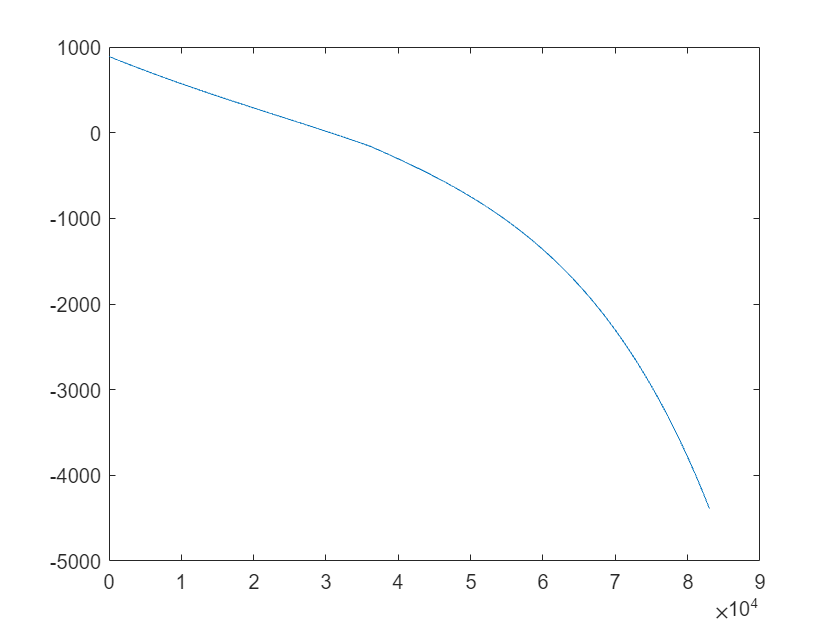


% end alt = ssl

% rate of climb
velocityRC = 300;

rateOfClimb = ((-(weight./((weight.*2./(wingArea.*altTable(:,4).*(velocityRC^2)))./(cd0 + (weight.*2./(wingArea.*altTable(:,4).*(velocityRC^2))).^2./(pi*e*AR))))*velocityRC)+(TaSSl*(altTable(:,4)/densitySSL)*velocityRC))/weight*10;
clf
plot(altTable(:,1),rateOfClimb)